# Cinéticas de Ozonización

## Experimento 1

Creación de objeto y carga de archivos:

clearvars
close all
clc
exp1 = laiiqatoolbox; % Crea el objeto
exp1.openfiles; % Abre venta de dialogo para seleccionar archivos

### Modificación de parámetros:

exp1.title = 'Experimento 1'; % Quitamos el titulo
exp1.xlabel = 'min'; % Unidades de tiempo en minutos para el eje x
exp1.xf{1} = 60; % La linea de datos 1 llega hasta 60 min
exp1.legend = {'default'}; % Nombres de leyenda = nombres de archivos

### Creación de gráfico:

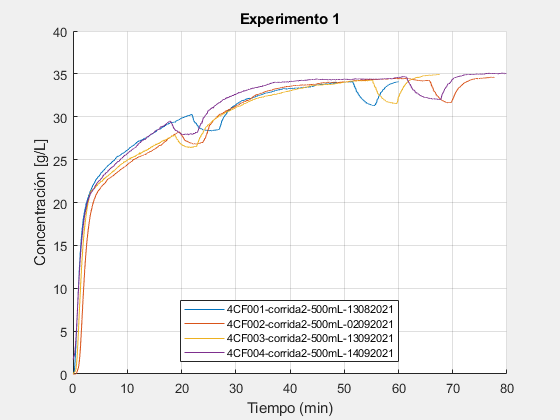

exp1.plotfiles; % Crea el objeto gráfico

### Cálculo de consumo de ozono del Experimento 1:

exp1.ozonecalc; % Calcula ozono consumido, residual y total para linea de datos

Para 4CF001-corrida2-500mL-13082021:
    Consumido: 0.27064 g/L
    Residual: 1.775 g/L
    Total: 2.0456 g/L en 60 min


Para 4CF002-corrida2-500mL-02092021:
    Consumido: 0.35836 g/L
    Residual: 2.3315 g/L
    Total: 2.6899 g/L en 77.69 min


Para 4CF003-corrida2-500mL-13092021:
    Consumido: 0.36634 g/L
    Residual: 1.9949 g/L
    Total: 2.3612 g/L en 67.55 min


Para 4CF004-corrida2-500mL-14092021:
    Consumido: 0.32065 g/L
    Residual: 2.4805 g/L
    Total: 2.8011 g/L en 79.81 min




## Experimento 2

Creación de objeto y carga de archivos:

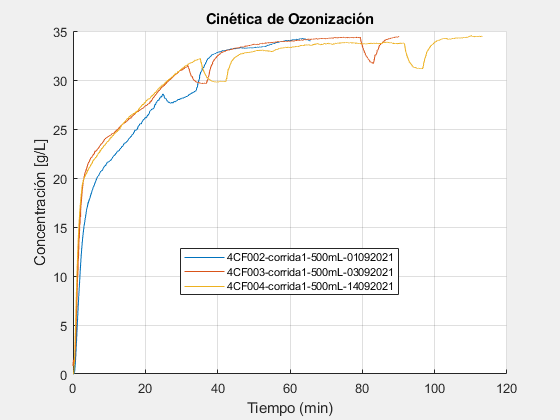

exp2 = laiiqatoolbox;
exp2.openfiles;
exp2.plotfiles;

### Modificación de parámetros:

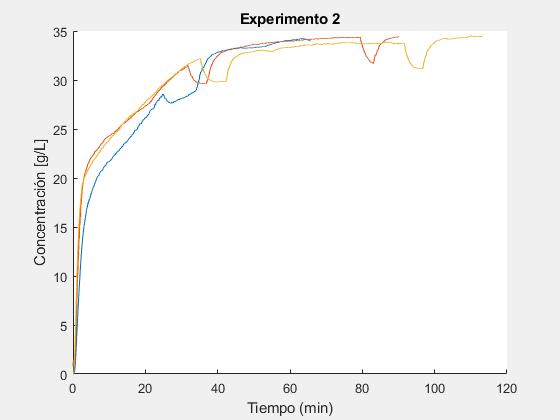

exp2.title = 'Experimento 2'; % Cambiamos titulo
exp2.legend = {}; % Desactiva las leyendas en el gráfico
exp2.grid = 'off'; % Quita las rejillas
exp2.plotfiles; % Aplicamos los cambios

Delimitar todas las lineas de datos a un valor de tiempo máximo:

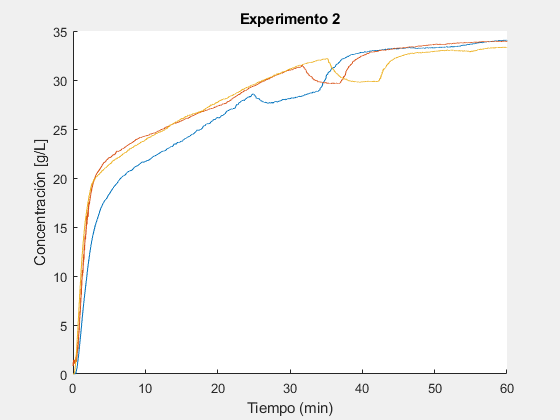

exp2.xf = {60 60 60}; % Delimita todos los datos a 60 minutos
exp2.plotfiles; % Aplica los cambios

Para el Experimento 2 se tienen 3 lineas de datos, modificamos la linea 1 y 2 para ajustarlas a la caida de concentración de la linea 3:

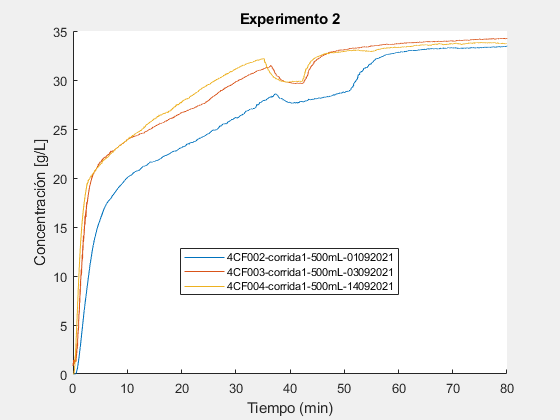

exp2.legend = {'default'}; % Restauramos las leyendas
exp2.xf = {'end' 'end' 'end'}; % Primero establecemos los valores por default de xf
exp2.xk = {1.5 1.15 1}; % Aumentamos el tiempo de la linea 1 en un 50%, linea 2 un 15% 
% y linea 3 sin aumentar
exp2.xf = {80 80 80}; % Cortamos los datos de todas las lineas a 80 minutos máximo
exp2.plotfiles; % Aplicamos los cambios

Guardado de figuras:

exp1.imageResolution = 800; % Resolución de la imagen de la figura 1 
% default = 300. Solo aplica para imagenes NO vectoriales.
exp2.imageResolution = 600; % Resolución de la imagen de la figura 2
exp2.title = ''; % Quitamos el titulo de la figura 2 dejando vacías las comillas cencillas
exp1.saveplot('MiExperimento1.png'); % Nombre y extensión de figura 1

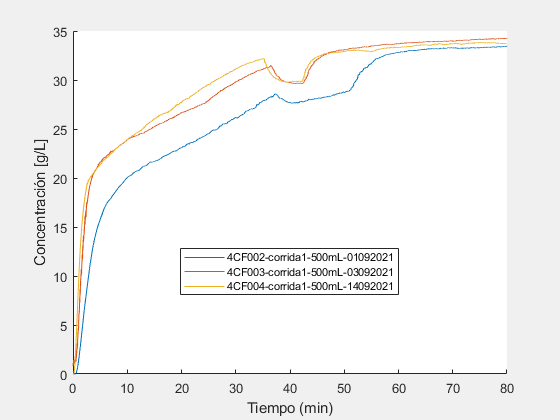

exp2.saveplot('MiExperimento2.png'); % Guardado de figura 2

Cálculo de ozono del Experimento 2:

exp2.ozonecalc;

Para 4CF002-corrida1-500mL-01092021:
    Consumido: 0.55067 g/L
    Residual: 2.1269 g/L
    Total: 2.6776 g/L en 80 min


Para 4CF003-corrida1-500mL-03092021:
    Consumido: 0.38828 g/L
    Residual: 2.3525 g/L
    Total: 2.7408 g/L en 80 min


Para 4CF004-corrida1-500mL-14092021:
    Consumido: 0.3302 g/L
    Residual: 2.3766 g/L
    Total: 2.7068 g/L en 80 min


